# Main Results 

This file contains the main results discussed in Section $5$ of *The Maslov index, degenerate crossings and the stability of pulse solutions to the Swift-Hohenberg equation*. 

## Introduction

We are interested in the Swift-Hohenberg equation with quadratic-cubic nonlinearity 

$u_t = -(1 + \partial_x^2)^2 u + f(u), \qquad f(u) = \nu u^2 - u^3 - \mu u.$.

We seek to determine the spectral stability of a stationary pulse solution $\varphi$. If we linearize about $\varphi$, form the eigenvalue problem and write the first order system, we obtain 


$$\dot q = B(x;\lambda)q, \qquad B(x; \lambda) = \pmatrix{0 & 0 & 0 & 1 \cr 0 & 0 & 1 & -2 \cr -\lambda - 1 + f'\circ\varphi(x) & 0 & 0 & 0 \cr  0 & 1 & 0 & 0 }.$$


We set $\nu = 1.6$ and $\mu = .05$. For the chosen parameters, there are two symmetric pulse solutions that can be approximated via the normal form solution 


$$u_\phi(x) = 2 \sqrt{\frac{2\mu}{\gamma}} \sech \left( \frac{x\sqrt\mu}{2} \right) \cos(x + \phi), \qquad \qquad \gamma = \frac{38\nu^2}{9} -3$$


with $\phi = 0, \pi$. We will compute the numerical results for both pulse solutions. 

% vector field parameters
vfParams.nu = 1.6;
vfParams.mu = .05;
vfParams.lambda = 0; 

% fourier approximation parameters
fourier.M = 1000; 
fourier.tol = 1e-14; 
fourier.order = 150; 
 
time = 100; 

## 
$$\phi = \pi$$
 

First we approximate the pulse solution that lies on the $\phi = \pi$ branch. We compute the Fourier series of the normal form $u_\phi$ and then perform Newton's method to refine the coefficients. More precisely, if we write the truncated Fourier expansion of the pulse solution as $\varphi^{(N)}(x) = \sum_{k = -N}^N a_k e^{i\pi k x/L}$ and define the vector of Fourier coefficients to be given by $a = (a_{-N}, \dots a_N)$, then we have the $2N + 1$system of ODES 

$ F(a)  = 0, \qquad  F_k(a)  =  \left[ - \mu - \left(1-\frac{k^2\pi^2}{L^2} \right)^2 \right]a_k - (a*a*a)_k + \nu (a*a)_k$,

where $(a*a)_k = \sum_{k_1 + k_2 = k} a_{k_1}a_{k_2}$ and $(a*a*a)_k = \sum_{k_1 + k_2 + k+3 = k} a_{k_1}a_{k_2}a_{k_3}$. 

normalForm.branch = pi; 

% initialize PulseSolution
S = PulseSolution(fourier, vfParams, normalForm, time);

% perform Newton's method
S = S.mainPulse();


                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          1           0.0941204                        1.12e+03              1
     1          2           0.0016934       0.446861           0.0492              1
     2          3         9.75539e-05       0.250844             17.4           1.12
     3          4         1.34005e-07      0.0408612             1.07           1.12
     4          5         3.12999e-13     0.00177101          0.00122           1.12
     5          6         3.10825e-24    2.10338e-06         1.85e-08           1.12

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 

We plot the normal form and the approximation of the pulse solution obtained via Newton's method. 

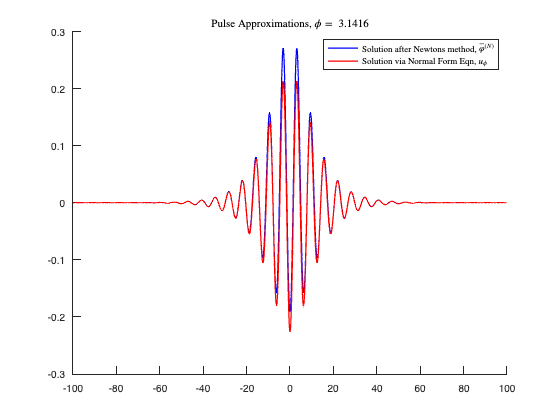

time = S.normalForm.time; 
sol = S.normalForm.sol(:,1);
full_sol = S.getFunctionFromFourierCoeffs(S.fourier.full_coeffs, "full");
figure 
hold on 
plot(full_sol(:, 1), full_sol(:, 2), color = 'b', LineWidth=1.25)
plot([-flip(time), time], [flip(sol), sol], Color  = 'r', LineWidth=1.25)
legend('Solution after Newtons method, $\bar \varphi^{(N)}$', 'Solution via Normal Form Eqn, $u_\phi$', Interpreter = 'latex')
title('Pulse Approximations, $\phi =$ ' + string(normalForm.branch), Interpreter = 'latex')

Now we compute the basis vectors for $E^u_-(x)$. We obtain one basis vector by differentiating our approximation of the pulse. We obtain the other basis vector by evolving an unstable eigenvector of the asymptotic coefficient matrix $B_\infty := \lim_{x \to - \infty} B(x; 0)$ under the variational flow.

% set parameters
conjPts.L = 55; 
C = ConjugatePoints(conjPts, vfParams);
C.Euminus.normalize = 1;
C.Euminus.refPlane = [1,4]; 

% compute conjugate points
[S,C] = C.mainConjPts(S);


Each basis vector for $E^u_-(x; 0)$ has four components. We plot each one against $x$. The plot of the basis vector obtained from one of the two asymptotic unstable eigenvectors, $W^{-,u}_1$ is as follows: 

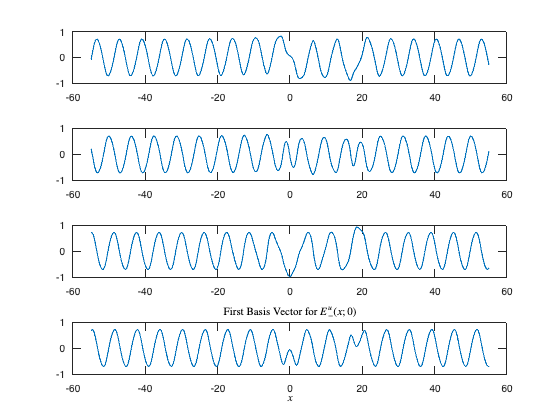


% Plot basis vectors for $E^u_-(x;0)$ 
time = C.Euminus.timeVec;
basis1 = reshape(C.Euminus.frame(:, 1,:), [4, max(size(time))]);
figure
tiledlayout(4,1)
nexttile
plot(time, basis1(1,:))
nexttile
plot(time, basis1(2,:))
nexttile
plot(time, basis1(3,:))
nexttile
plot(time, basis1(4,:))
title('First Basis Vector for $E^u_-(x; 0)$', Interpreter = 'latex')
xlabel('$x$', Interpreter = 'latex')

The plot of the basis vector formed from the derivative of the pulse, $W_2^{-,u}$ is as follows: 

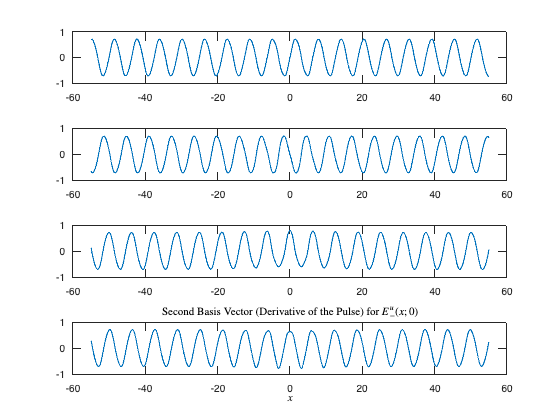


basis2 = reshape(C.Euminus.frame(:, 2,:), [4, max(size(time))]);
figure
tiledlayout(4,1)
nexttile
plot(time, basis2(1,:))
nexttile
plot(time, basis2(2,:))
nexttile
plot(time, basis2(3,:))
nexttile
plot(time, basis2(4,:))
title('Second Basis Vector (Derivative of the Pulse) for $E^u_-(x; 0)$', Interpreter='latex')
xlabel('$x$', Interpreter = 'latex')

We choose to normalize both of these solutions so that they have norm $1$. This prevents exponential growth in the determinant plot. Define

$E^u_-(x) = \pmatrix{ | & | \cr W_1^{-,u} & W^{-,u}_2 \cr | & |  } \quad \text{ and } \quad A(x) = \pmatrix{ (W_1^{-,u})_1 & (W_2^{-,u})_1 \cr (W_1^{-,u})_4 & (W_2^{-,u})_4}$.

We plot $\det A(x)$ below.  

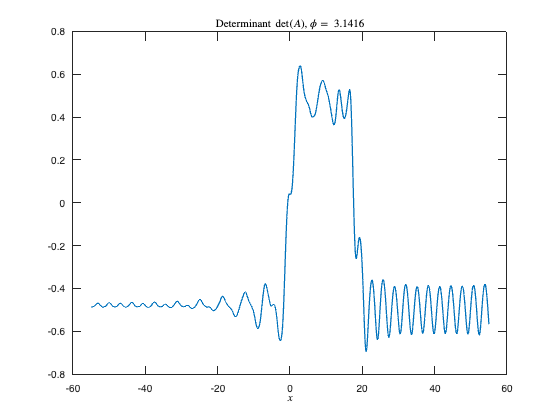

% plot determinant function 

dets = C.conjPts.dets{:, 3}; 
time = C.conjPts.dets{:,2}; 

figure 
plot(time, dets, LineWidth=1.25)
title('Determinant $\det(A)$, $\phi =$ ' + string(normalForm.branch), Interpreter='latex')
xlabel('$x$', Interpreter = 'latex')

We find the zeros of $\det A(x)$ to have $x$ values 

conj_ind = find([0, diff(sign(dets))] ~= 0);
conj_pts = time(conj_ind);

disp('Conjugate points locations (x): ')

Conjugate points locations (x): 


disp(conj_pts)

   -0.6310
   17.5887


We can approximate the unstable eigenvalues of the eigenvalue equation by finding the spectrum of $DF$, where $F$ describes the ODEs satisfied by the Fourier coefficients. 

% print eigenvalues 

disp('Eigenvalue approximation via Fourier modes: ')

Eigenvalue approximation via Fourier modes: 


disp(S.fourier.unstable_eigs)

    0.0058
    0.1179


disp("We found " + string(max(size(S.fourier.unstable_eigs))) + " eigenvalue(s) and "...
    + string(max(size(conj_pts))) + " conjugate points for the pulse with phase " ...
    +'phi = ' + string(normalForm.branch))

We found 2 eigenvalues and 2 conjugate points for the pulse with phase phi = 3.1416


## 
$$\phi = 0$$


Now we perform the same computations for the other pulse solution. First we perform Newton's method to obtain an approximation of the pulse. 

clear;
normalForm.branch = 0; 

% vector field parameters
vfParams.nu = 1.6;
vfParams.mu = .05;
vfParams.lambda = 0; 

% fourier approximation parameters
fourier.M = 1000; 
fourier.tol = 1e-14; 
fourier.order = 150; 
 
time = 100; 

% initialize PulseSolution
S = PulseSolution(fourier, vfParams, normalForm, time);

% perform Newton's method
S = S.mainPulse();


                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          1           0.0882328                             459              1
     1          2          0.00177027       0.452275              143              1
     2          3         0.000400908       0.338144              2.3           1.13
     3          4         9.11572e-06       0.140264             8.11           1.13
     4          5         5.59227e-09      0.0185436            0.265           1.13
     5          6         1.31738e-15    0.000447843         1.45e-05           1.13
     6          7         1.46332e-24    2.24371e-07          1.5e-08           1.13

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the 

We plot the normal form and the pulse approximation. 

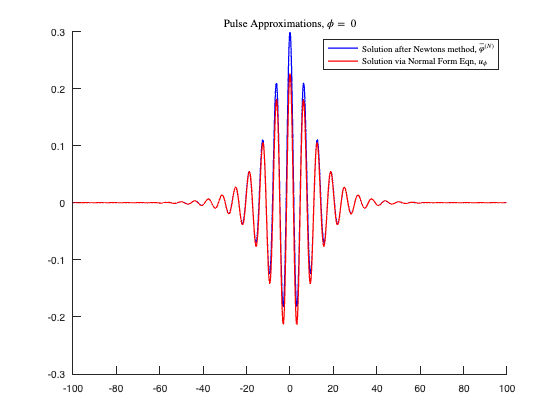

time = S.normalForm.time; 
sol = S.normalForm.sol(:,1);
full_sol = S.getFunctionFromFourierCoeffs(S.fourier.full_coeffs, "full");
figure 
hold on 
plot(full_sol(:, 1), full_sol(:, 2), color = 'b', LineWidth=1.25)
plot([-flip(time), time], [flip(sol), sol], Color  = 'r', LineWidth=1.25)
legend('Solution after Newtons method, $\bar \varphi^{(N)}$', 'Solution via Normal Form Eqn, $u_\phi$', Interpreter = 'latex')
title('Pulse Approximations, $\phi =$ ' + string(normalForm.branch), Interpreter = 'latex')

We compute the basis vectors for $E^u_-(x; 0)$ and plot them. The second basis vector is again formed from the derivative of the pulse. 

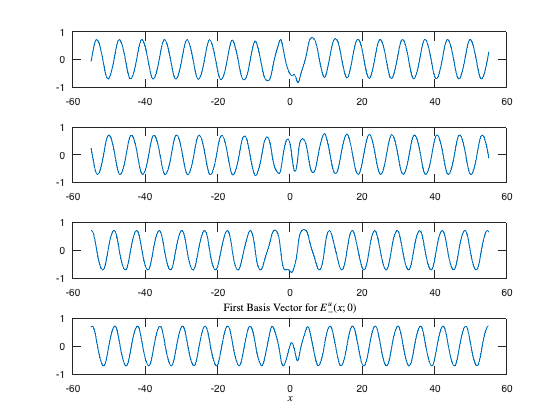

% set parameters
conjPts.L = 55; 
C = ConjugatePoints(conjPts, vfParams);
C.Euminus.normalize = 1;
C.Euminus.refPlane = [1,4]; 

% compute conjugate points
[S,C] = C.mainConjPts(S);


% Plot basis vectors for $E^u_-(x;0)$ 
time = C.Euminus.timeVec;
basis1 = reshape(C.Euminus.frame(:, 1,:), [4, max(size(time))]);
figure
tiledlayout(4,1)
nexttile
plot(time, basis1(1,:))
nexttile
plot(time, basis1(2,:))
nexttile
plot(time, basis1(3,:))
nexttile
plot(time, basis1(4,:))
title('First Basis Vector for $E^u_-(x; 0)$', Interpreter = 'latex')
xlabel('$x$', Interpreter = 'latex')

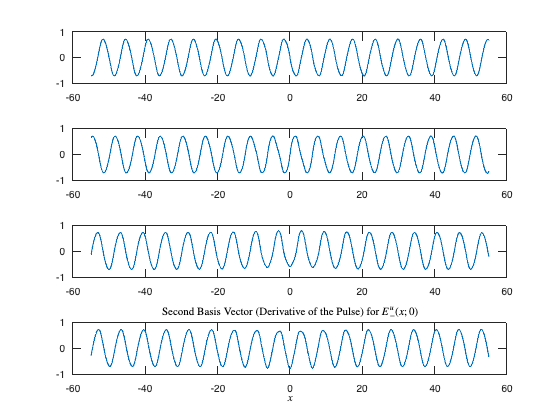



basis2 = reshape(C.Euminus.frame(:, 2,:), [4, max(size(time))]);
figure
tiledlayout(4,1)
nexttile
plot(time, basis2(1,:))
nexttile
plot(time, basis2(2,:))
nexttile
plot(time, basis2(3,:))
nexttile
plot(time, basis2(4,:))
title('Second Basis Vector (Derivative of the Pulse) for $E^u_-(x; 0)$', Interpreter='latex')
xlabel('$x$', Interpreter = 'latex')

Forming $A(x)$ as above, we can plot the determinant function. 

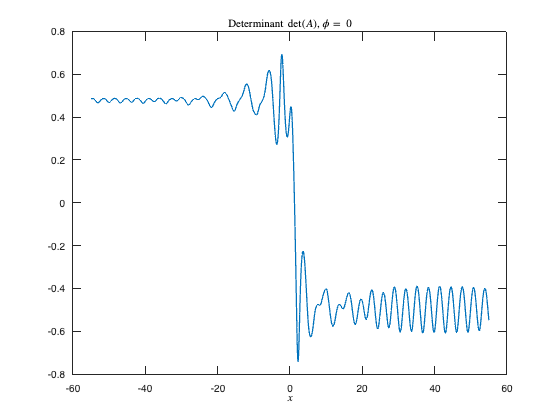

% plot determinant function 

dets = C.conjPts.dets{:, 3}; 
time = C.conjPts.dets{:,2}; 

figure 
plot(time, dets, LineWidth=1.25)
title('Determinant $\det(A)$, $\phi =$ ' + string(normalForm.branch), Interpreter='latex')
xlabel('$x$', Interpreter = 'latex')

We find the zeros of $\det A(x)$ to have $x$ values 

conj_ind = find([0, diff(sign(dets))] ~= 0);
conj_pts = time(conj_ind);

disp('Conjugate points locations (x): ')

Conjugate points locations (x): 


disp(conj_pts)

    1.2402


We can approximate the unstable eigenvalues of the eigenvalue equation by finding the spectrum of $DF$, where $F$ describes the ODEs satisfied by the Fourier coefficients. 

% print eigenvalues 

disp('Eigenvalue approximation via Fourier modes: ')

Eigenvalue approximation via Fourier modes: 


disp(S.fourier.unstable_eigs)

    0.1209


disp("We found " + string(max(size(S.fourier.unstable_eigs))) + " eigenvalue(s) and "...
    + string(max(size(conj_pts))) + " conjugate points for the pulse with phase " ...
    +'phi = ' + string(normalForm.branch))

We found 1 eigenvalues and 1 conjugate points for the pulse with phase phi = 0
